# Análisis cinemático de un manipulador serial 6 DoF

**Universidad EIA — Ingeniería Mecatrónica — Robótica**

**Parcial No. 2, Punto No. 1 — Robot: FANUC LR Mate 200iD**

encontrar los seis ángulos articulares que el robot debe adoptar en cada punto, filtrar las soluciones válidas y animar el movimiento.

El problema tiene dos direcciones opuestas:

- **Cinemática directa (FK)**: dados los seis ángulos, ¿dónde queda la punta? Es fácil: se multiplican seis matrices.

- **Cinemática inversa (IK)**: dada la punta, ¿qué ángulos se necesitan? Es el problema difícil y el núcleo de este taller.

Todas las funciones están al final del documento, en la sección *Funciones locales*.

clear; clc; close all;

## 1. Parámetros del robot

Un manipulador queda descrito por unas pocas longitudes. Éstas son las de la Tabla 1 del enunciado, convertidas de cm a mm para trabajar en unidades consistentes con el volumen de trabajo.

El significado físico de cada una:

- `L1`: separación horizontal entre el eje de la base y el hombro

- `L2`: altura de la base hasta el hombro

- `L3`: brazo (hombro al codo)

- `L4`: pequeño desfase del codo

- `L5`: antebrazo (codo al centro de muñeca)

- `L6`: de la muñeca a la punta de la herramienta (TCP)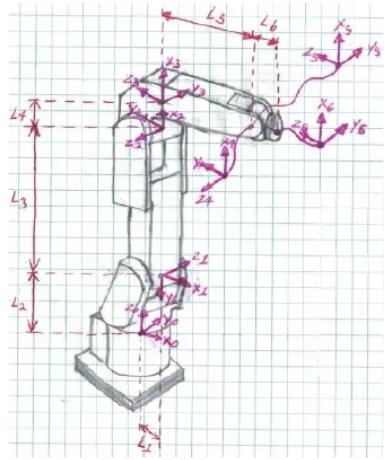

P = ParametrosRobot();
disp(P)

         L1: 65
         L2: 150
         L3: 310
         L4: 60
         L5: 325
         L6: 70
       qlim: [6×2 double]
    tolSing: 1.0000e-06
     tolDet: 1.0000e-09



## 2. La tabla Denavit-Hartenberg

- $a$ : qué tan largo es el eslabón

- $\alpha$ : qué tan torcido está respecto al anterior

- $d$ : desplazamiento a lo largo del eje de giro

- $\theta$ : el ángulo del motor (la **única variable**)

Cada fila se convierte en una matriz homogénea 4x4 que representa "cómo pasar del eslabón anterior al siguiente":


$$^{i-1}A_i = \mathrm{Rot}_z(\theta)\,\mathrm{Tras}_z(d)\,\mathrm{Tras}_x(a)\,\mathrm{Rot}_x(\alpha)$$


Ésta es la Tabla 2 del enunciado. Nótese el desfase de $-90^\circ$ en $\theta_2$: es una convención del fabricante para que el cero del motor 2 coincida con el brazo vertical.

q_prueba = deg2rad([0 0 0 0 0 0]);          % robot en posición de cero
DH = TablaDH(q_prueba, P);

disp(array2table([DH(:,1), rad2deg(DH(:,2)), DH(:,3), rad2deg(DH(:,4))], ...
    'VariableNames', {'a_mm','alpha_deg','d_mm','theta_deg'}, ...
    'RowNames', {'0A1','1A2','2A3','3A4','4A5','5A6'}))

           a_mm    alpha_deg    d_mm    theta_deg
           ____    _________    ____    _________

    0A1     65        -90        150         0   
    1A2    310        180          0       -90   
    2A3     60        -90          0         0   
    3A4      0         90       -325         0   
    4A5      0        -90          0         0   
    5A6      0          0        -70         0   



**El dato clave:** en las filas 4, 5 y 6 se cumple que $a = 0$ y, además, $d_5 = 0$. Eso significa que los ejes 4, 5 y 6 **se cortan todos en un mismo punto**. A esa configuración se le llama **muñeca esférica. (Tema Enseñado por Manuel en Clase)**

## 3. Cinemática directa

Multiplicando las seis matrices en orden se obtiene la posición y la orientación de la punta respecto a la base:


$$^0T_6 = {}^0A_1 \cdot {}^1A_2 \cdot {}^2A_3 \cdot {}^3A_4 \cdot {}^4A_5 \cdot {}^5A_6$$


En la matriz resultante, la última columna es la **posición** del TCP y las tres primeras son los ejes $x_6$, $y_6$, $z_6$ de la herramienta, es decir su **orientación**.

q_test = deg2rad([30 -20 15 0 45 0]);
T06 = FK(q_test, P);

fprintf('Posición del TCP: [%.1f  %.1f  %.1f] mm\n', T06(1:3,4));

Posición del TCP: [175.8  101.5  745.8] mm


disp('Matriz 0T6:'); disp(T06)

Matriz 0T6:
   -0.8529   -0.5000   -0.1504  175.7503
   -0.4924    0.8660   -0.0868  101.4695
    0.1736         0   -0.9848  745.8027
         0         0         0    1.0000



## 4. desacople

El punto donde se cortan los ejes 4, 5 y 6 se llama **centro de muñeca**. Ese punto **no se mueve** cuando giran los motores 4, 5 y 6

- El centro de muñeca depende **sólo** de $\theta_1,\theta_2,\theta_3$ → resuelven la **posición**

- Los ángulos $\theta_4,\theta_5,\theta_6$ resuelven la **orientación** que falta

Y calcularlo es trivial: se toma el TCP y se retrocede $L_6$ milímetros a lo largo del eje 6.


$$P_c = {}^0q_{o6} + L_6\,{}^0\vec{S}_6$$


## 5. Los cuatro pasos de la cinemática inversa

**Paso A — $\theta_1$.**  Hay **dos** soluciones: el robot también puede girar 180° y alcanzar el punto estirándose hacia atrás.


$$\theta_1 = \mathrm{atan2}(p_y,\,p_x) \qquad [\,+\pi\ \textrm{para la 2da rama}\,]$$


**Paso B — $\theta_3$.**  Al sumar los cuadrados, $\theta_2$ desaparece solo y queda una ecuación de la forma $A\cos\theta_3 + B\sin\theta_3 = -D$, que se resuelve así:


$$h=\sqrt{A^2+B^2}, \qquad \theta_3 = \pm\arccos\!\left(\frac{-D}{h}\right) + \mathrm{atan2}(B,A)$$


El $\pm$ son las dos soluciones clásicas: **codo arriba** y **codo abajo**.

**Paso C — $\theta_2$.** Conocido $\theta_3$, las ecuaciones restantes son **lineales** en $\cos\theta_2$ y $\sin\theta_2$. Un sistema 2x2 que se resuelve por la regla de Cramer. Aquí no hay $\pm$: $\theta_2$ queda determinado.

**Paso D — $\theta_4,\theta_5,\theta_6$.** Ya se sabe cómo quedó orientado el codo, así que se calcula la rotación que **todavía falta**:


$$b = ({}^0R_3)^{T}\cdot{}^0R_6$$


El $\pm$ del arcocoseno son las dos posturas de muñeca: normal o volteada.


$$\theta_5=\pm\arccos(b_{33}), \quad \theta_6=\mathrm{atan2}\!\left(\frac{-b_{32}}{s_5},\frac{b_{31}}{s_5}\right), \quad \theta_4=\mathrm{atan2}\!\left(\frac{-b_{23}}{s_5},\frac{-b_{13}}{s_5}\right)$$


**Conteo de soluciones:** 2 ($\theta_1$) x 2 ($\theta_3$) x 2 ($\theta_5$) = **8 configuraciones**. Ése es el origen de las ocho columnas de la ecuación (1) del enunciado: el robot llega al mismo punto, con la misma orientación, de ocho maneras distintas.

## 6. Definición de la trayectoria

La trayectoria debe tener al menos 25 puntos y variar posición **y** orientación. Aquí se traza un corazón sobre un plano vertical situado frente al robot, como si dibujara sobre una pared.

**Detalle importante:** la orientación NO se amarra a la tangente de la curva. En la punta inferior del corazón la tangente se invierte de golpe y aparecerían saltos articulares de ~154° entre dos puntos consecutivos, lo que arruina la animación. Se usa en cambio un giro y un cabeceo suaves, que igual cumplen el requisito de variar la orientación.

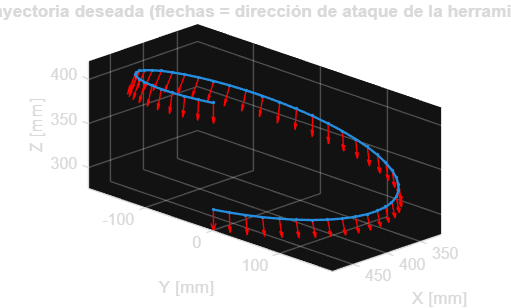

n     = 50;             % número de puntos (>= 25 exigidos)
FORMA = 'helice';      % 'corazon' o 'helice'

[Q6, S6, A67] = Trayectoria(n, P, FORMA);

figure('Color','w');
plot3(Q6(:,1), Q6(:,2), Q6(:,3), '.-', 'LineWidth',1.4); hold on
quiver3(Q6(:,1),Q6(:,2),Q6(:,3), -S6(:,1),-S6(:,2),-S6(:,3), 0.4, 'r');
grid on; axis equal; view(135,20);
xlabel('X [mm]'); ylabel('Y [mm]'); zlabel('Z [mm]');
title('Trayectoria deseada (flechas = dirección de ataque de la herramienta)');

## 7. Solución general: la matriz SlnSet

Se recorre punto por punto llamando a la cinemática inversa. Para **cada** punto se obtienen 8 configuraciones, así que el resultado es una matriz tridimensional de $n\times 6\times 8$: cada "capa" (tercera dimensión) es una configuración seguida a lo largo de toda la trayectoria.

Cuando una rama no existe se guarda `NaN`. ¿Cuándo no existe? Cuando el arcocoseno recibe un número mayor que 1, lo que geométricamente significa *ese punto está fuera del alcance del brazo*. Es el equivalente a los resultados complejos que menciona el enunciado, y el código lo atrapa antes de que aparezcan.

SlnSet = NaN(n,6,8);
for i = 1:n                                  % ciclo sobre los puntos
    SlnPoint      = IK(Q6(i,:).', S6(i,:).', A67(i,:).', P);   % 6x8
    SlnSet(i,:,:) = reshape(SlnPoint, [1 6 8]);
end

disp('Las 8 configuraciones del PRIMER punto (grados):');

Las 8 configuraciones del PRIMER punto (grados):


disp(array2table(rad2deg(squeeze(SlnSet(1,:,:))), ...
    'VariableNames', cellstr(compose('Cfg%d',1:8)), ...
    'RowNames', {'th1','th2','th3','th4','th5','th6'}))

            Cfg1      Cfg2       Cfg3       Cfg4       Cfg5       Cfg6       Cfg7       Cfg8  
           ______    _______    _______    _______    _______    _______    _______    _______

    th1         0          0          0          0        180        180        180        180
    th2    106.63     106.63     17.512     17.512    -43.791    -43.791    -92.244    -92.244
    th3    165.26     165.26    -6.1777    -6.1777      126.4      126.4     32.676     32.676
    th4      -180          0       -180          0          0        180          0        180
    th5    148.63    -148.63     66.311    -66.311     99.805    -99.805

## 8. Solución particular: filtrado por capas

La verificación se hace **capa por capa**, nunca mezclando entre ellas. Si una configuración falla aunque sea en un solo punto, se descarta completa.

La razón es física: saltar de una capa a otra a mitad de camino significaría que el robot se reconfigura en pleno movimiento, lo cual no es una trayectoria ejecutable.

[SlnSetVer, capasVal, detalle] = Filtrar(SlnSet);

for k = 1:8
    if any(capasVal==k), estado = 'CONSERVADA'; else, estado = 'DESCARTADA'; end
    fprintf('  Configuración %d : %2d/%2d puntos válidos  -> %s\n', ...
        k, detalle(k), n, estado);
end

  Configuración 1 : 50/50 puntos válidos  -> CONSERVADA
  Configuración 2 : 50/50 puntos válidos  -> CONSERVADA
  Configuración 3 : 50/50 puntos válidos  -> CONSERVADA
  Configuración 4 : 50/50 puntos válidos  -> CONSERVADA
  Configuración 5 : 49/50 puntos válidos  -> DESCARTADA
  Configuración 6 : 49/50 puntos válidos  -> DESCARTADA
  Configuración 7 : 49/50 puntos válidos  -> DESCARTADA
  Configuración 8 : 49/50 puntos válidos  -> DESCARTADA


fprintf('\nSlnSetVer: %d x %d x %d\n', size(SlnSetVer,1), size(SlnSetVer,2), size(SlnSetVer,3));


SlnSetVer: 50 x 6 x 4


## 9. Selección de la configuración a ejecutar

Entre las capas sobrevivientes se escoge la de **menor recorrido articular total**, es decir la más suave. Antes se aplica `unwrap` para eliminar saltos artificiales de $\pm 2\pi$ que no corresponden a movimiento real.

Opcionalmente se descartan las capas que violan los límites físicos de los motores. Sin este filtro, el criterio de suavidad puede escoger una postura en la que el robot se estira hacia atrás por encima de su propia base.

**Advertencia:** los límites almacenados son los del catálogo, pero el $\theta_2$ de esta tabla DH no es exactamente el eje J2 del fabricante. Son por tanto una aproximación razonable, no una equivalencia exacta.

USAR_LIMITES = true;
[Qsel, kSel, costo] = Seleccionar(SlnSetVer, capasVal, P, USAR_LIMITES);

for j = 1:numel(capasVal)
    fprintf('  Capa %d -> recorrido = %8.2f rad\n', capasVal(j), costo(j));
end

  Capa 1 -> recorrido =      Inf rad
  Capa 2 -> recorrido =      Inf rad
  Capa 3 -> recorrido =     5.99 rad
  Capa 4 -> recorrido =     5.99 rad


fprintf('\n  >> Configuración ejecutada: %d\n', kSel);


  >> Configuración ejecutada: 3


## 10. Verificación: FK(IK) debe devolver el punto original

Ésta es la red de seguridad. Si la inversa está bien deducida, pasar sus resultados por la directa tiene que devolver exactamente el punto pedido.

Un error del orden de $10^{-11}$ confirma que las fórmulas son correctas. Si diera milímetros o grados, alguna fórmula estaría mal trasladada.

errPos = zeros(n,1);  errOri = zeros(n,1);
for i = 1:n
    T = FK(Qsel(i,:), P);
    errPos(i) = norm(T(1:3,4) - Q6(i,:).');
    errOri(i) = rad2deg(acos(max(min(T(1:3,3).'*S6(i,:).',1),-1)));
end
fprintf('  Error de posición    máx = %.3e mm\n',  max(errPos));

  Error de posición    máx = 1.933e-13 mm


fprintf('  Error de orientación máx = %.3e grados\n', max(errOri));

  Error de orientación máx = 1.207e-06 grados


## 11. Perfiles articulares

Cómo se mueve cada motor a lo largo de la trayectoria. Curvas suaves, sin escalones, indican una trayectoria ejecutable por el robot real.

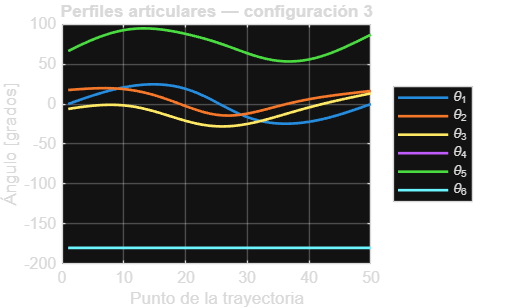

figure('Color','w');
plot(1:n, rad2deg(Qsel), 'LineWidth',1.6); grid on
xlabel('Punto de la trayectoria'); ylabel('Ángulo [grados]');
legend({'\theta_1','\theta_2','\theta_3','\theta_4','\theta_5','\theta_6'}, ...
    'Location','eastoutside');
title(sprintf('Perfiles articulares — configuración %d', kSel));


fprintf('  Salto máximo entre puntos consecutivos: %.1f grados\n', ...
    max(max(abs(diff(rad2deg(Qsel))))));

  Salto máximo entre puntos consecutivos: 4.1 grados


## 12. Animación con trazado en tiempo real

Cada cuadro llama a la cinemática directa para saber dónde está cada articulación, dibuja el esqueleto del robot y añade un punto al trazo del TCP.

**Nota:** dentro del Live Editor la animación puede verse lenta porque la figura se renderiza en línea. Para verla fluida, haga clic derecho sobre la figura y elija mostrarla en una ventana aparte.

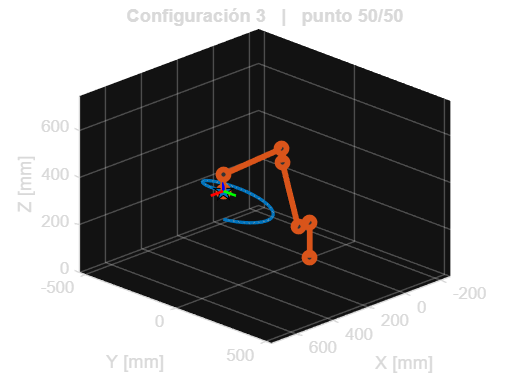

Animar(Qsel, Q6, P, kSel, 0.05);

## Funciones locales

 todas las funciones deben ir en el documento. (PALABRAS MÁS, PALABRAS MENOS, LA CARPINTERIA DEL TRABAJO)

function P = ParametrosRobot()
% Longitudes [mm] y límites articulares del FANUC LR Mate 200iD.
P.L1 =  65;   P.L2 = 150;   P.L3 = 310;
P.L4 =  60;   P.L5 = 325;   P.L6 =  70;

P.qlim = deg2rad([-170 170; -100 145; -205 205; -190 190; -125 125; -360 360]);
P.tolSing = 1e-6;    % |sin(th5)| menor a esto => singularidad de muñeca
P.tolDet  = 1e-9;    % determinante del sistema lineal de theta2
end

% ---------------------------------------------------------------------
function DH = TablaDH(q, P)
% Tabla DH [a, alpha, d, theta] evaluada en q. Única definición del robot.
DH = [ P.L1, -pi/2,  P.L2,  q(1)        ;
       P.L3,    pi,     0,  q(2) - pi/2 ;
       P.L4, -pi/2,     0,  q(3)        ;
          0,  pi/2, -P.L5,  q(4)        ;
          0, -pi/2,     0,  q(5)        ;
          0,     0, -P.L6,  q(6)       ];
end

% ---------------------------------------------------------------------
function T = MatrizDH(a, alpha, d, theta)
% Convierte una fila DH en su matriz homogénea 4x4.
ct = cos(theta); st = sin(theta); ca = cos(alpha); sa = sin(alpha);
T = [ ct, -st*ca,  st*sa, a*ct ;
      st,  ct*ca, -ct*sa, a*st ;
       0,     sa,     ca,    d ;
       0,      0,      0,    1 ];
T(abs(T) < 1e-12) = 0;      % limpia residuos tipo cos(pi/2)=6.1e-17
end

% ---------------------------------------------------------------------
function [T06, T0i, Pts] = FK(q, P)
% CINEMÁTICA DIRECTA. Multiplica las seis matrices en orden.
DH  = TablaDH(q, P);
T0i = cell(1,6);  T = eye(4);
for i = 1:6
    T = T * MatrizDH(DH(i,1), DH(i,2), DH(i,3), DH(i,4));
    T0i{i} = T;
end
T06 = T0i{end};

if nargout > 2                       % puntos para dibujar el esqueleto
    Pts = zeros(3,8);
    Pts(:,1) = [0;0;0];  Pts(:,2) = [0;0;P.L2];
    for i = 1:6, Pts(:,i+2) = T0i{i}(1:3,4); end
end
end

% ---------------------------------------------------------------------
function SlnSetPoint = IK(q_f6, S_f6, a_f67, P)
% CINEMÁTICA INVERSA por desacople. Devuelve una matriz 6x8.
% Las ramas inexistentes quedan en NaN.

% Marco del efector final, ortogonalizado por seguridad
S_f6  = S_f6(:)/norm(S_f6);
a_f67 = a_f67(:) - (a_f67(:).'*S_f6)*S_f6;
a_f67 = a_f67/norm(a_f67);
R_f6  = [a_f67, cross(S_f6,a_f67), S_f6];

SlnSetPoint = NaN(6,8);

% --- Centro de muñeca: se retrocede L6 a lo largo del eje 6 ---
Pc = q_f6(:) + P.L6*S_f6;
px = Pc(1); py = Pc(2); pz = Pc(3);

% --- PASO A: theta1 (2 ramas) ---
th1_vec = [atan2(py,px), atan2(py,px)+pi];

for i1 = 1:2
    th1 = th1_vec(i1);  c1 = cos(th1); s1 = sin(th1);

    Rr = c1*px + s1*py - P.L1;    % centro de muñeca visto desde el marco 1
    Zc = P.L2 - pz;
    Wc = -s1*px + c1*py;          % vale 0: de ahí salió theta1

    % --- PASO B: theta3 por suma de cuadrados (2 ramas: codo arriba/abajo) ---
    SS = Rr^2 + Zc^2 + Wc^2;
    A  = 2*P.L3*P.L4;
    B  = 2*P.L3*P.L5;
    D  = -(SS - (P.L3^2 + P.L4^2 + P.L5^2));
    h  = sqrt(A^2 + B^2);
    arg = -D/h;

    if abs(arg) > 1, continue; end        % fuera de alcance -> NaN

    th3_vec = [acos(arg), -acos(arg)] + atan2(B,A);

    for i3 = 1:2
        th3 = th3_vec(i3);

        % --- PASO C: theta2, sistema lineal 2x2 (Cramer) ---
        u = P.L4*cos(th3) + P.L5*sin(th3);
        v = P.L4*sin(th3) - P.L5*cos(th3);
        Amat2 = [-v, u+P.L3; -(u+P.L3), -v];
        Bvec2 = [Rr; Zc];
        det2  = v^2 + (u+P.L3)^2;
        if abs(det2) < P.tolDet, continue; end

        cos_th2 = (Bvec2(1)*Amat2(2,2) - Bvec2(2)*Amat2(1,2)) / det2;
        sin_th2 = (Amat2(1,1)*Bvec2(2) - Amat2(2,1)*Bvec2(1)) / det2;
        th2     = atan2(sin_th2, cos_th2);

        % --- PASO D: orientación. b es la rotación que todavía falta ---
        [~, T0i] = FK([th1 th2 th3 0 0 0], P);
        b = T0i{3}(1:3,1:3).' * R_f6;

        b33 = max(min(b(3,3),1),-1);
        th5_vec = [acos(b33), -acos(b33)];

        for i5 = 1:2
            th5 = th5_vec(i5);  s5 = sin(th5);
            k = (i1-1)*4 + (i3-1)*2 + i5;      % columna 1..8

            if abs(s5) < P.tolSing, continue; end   % singularidad de muñeca

            th6 = atan2(-b(3,2)/s5,  b(3,1)/s5);
            th4 = atan2(-b(2,3)/s5, -b(1,3)/s5);
            SlnSetPoint(:,k) = [th1; th2; th3; th4; th5; th6];
        end
    end
end
end

% ---------------------------------------------------------------------
function [Q6, S6, A67] = Trayectoria(n, P, forma)
% Genera n puntos con posición y orientación variables.
t = linspace(0,1,n).';
S6 = zeros(n,3); A67 = zeros(n,3);

switch lower(forma)
    case 'helice'          % círculo en XY + ascenso en Z
        x = 400 + 80*cos(2*pi*t);
        y =       180*sin(2*pi*t);
        z = 300 + 120*t;
        gamma = atan2(y,x);
        beta  = deg2rad(25)*sin(2*pi*t);
        for i = 1:n
            Rz = [cos(gamma(i)) -sin(gamma(i)) 0; sin(gamma(i)) cos(gamma(i)) 0; 0 0 1];
            Ry = [cos(beta(i)) 0 sin(beta(i)); 0 1 0; -sin(beta(i)) 0 cos(beta(i))];
            R  = Rz*Ry;
            S6(i,:) = R(:,3).';   A67(i,:) = R(:,1).';
        end

    case 'corazon'         % curva clásica sobre un plano vertical x = xp
        xp = 420; zc = 380; k = 6;
        u  = 2*pi*t;
        x  = xp*ones(n,1);
        y  = k*(16*sin(u).^3);
        z  = zc + k*(13*cos(u) - 5*cos(2*u) - 2*cos(3*u) - cos(4*u));
        phi  = deg2rad(60)*sin(2*pi*t);
        beta = deg2rad(20)*sin(2*pi*t);
        for i = 1:n
            a = [0, cos(phi(i)), sin(phi(i))];
            A67(i,:) = a;
            S6(i,:)  = Rodrigues([-1 0 0], a, beta(i));
        end

    otherwise
        error('Forma no reconocida: use ''helice'' o ''corazon''.');
end

Q6 = [x, y, z];

% Aviso si algún punto queda fuera del alcance geométrico
dmin = abs(P.L3 - hypot(P.L4,P.L5));   dmax = P.L3 + hypot(P.L4,P.L5);
for i = 1:n
    Pc = Q6(i,:).' + P.L6*S6(i,:).';
    d  = norm([hypot(Pc(1),Pc(2)) - P.L1; Pc(3) - P.L2]);
    if d < dmin || d > dmax
        warning('Punto %d fuera del alcance (d = %.1f mm).', i, d);
    end
end
end

% ---------------------------------------------------------------------
function v = Rodrigues(v, k, ang)
% Rota el vector v un ángulo ang alrededor del eje k.
v = v(:).';  k = k(:).'/norm(k);
v = v*cos(ang) + cross(k,v)*sin(ang) + k*(dot(k,v))*(1-cos(ang));
end

% ---------------------------------------------------------------------
function [SlnSetVer, capasVal, detalle] = Filtrar(SlnSet)
% Verificación POR CAPAS: una capa se conserva sólo si es válida en TODOS
% los puntos. Nunca se mezclan capas entre sí.
[n,~,nCfg] = size(SlnSet);
detalle = zeros(1,nCfg);   capasVal = [];

for k = 1:nCfg
    capa = SlnSet(:,:,k);
    ok   = isfinite(real(capa)) & abs(imag(capa)) < 1e-9;
    detalle(k) = sum(all(ok,2));
    if detalle(k) == n
        capasVal(end+1) = k; %#ok<AGROW>
    end
end

if isempty(capasVal)
    SlnSetVer = [];
    error('Ninguna configuración es válida en todos los puntos.');
else
    SlnSetVer = real(SlnSet(:,:,capasVal));
end
end

% ---------------------------------------------------------------------
function [Qsel, kSel, costo] = Seleccionar(SlnSetVer, capasVal, P, usarLimites)
% Escoge la capa de menor recorrido articular total (la más suave).
[n,~,m] = size(SlnSetVer);
costo = inf(1,m);

for j = 1:m
    Q = unwrap(SlnSetVer(:,:,j), [], 1);        % elimina saltos de +-2*pi
    if usarLimites
        fuera = any(any(Q < repmat(P.qlim(:,1).',n,1) | ...
                        Q > repmat(P.qlim(:,2).',n,1)));
        if fuera, continue; end
    end
    costo(j) = sum(sum(abs(diff(Q,1,1))));
end

[~,j] = min(costo);
if ~isfinite(costo(j))
    error('Ninguna capa cumple los límites. Desactive USAR_LIMITES.');
end
Qsel = unwrap(SlnSetVer(:,:,j), [], 1);
kSel = capasVal(j);
end

% ---------------------------------------------------------------------
function Animar(Q, Q6, P, kSel, pausa)
% Animación 3D con trazado del TCP en tiempo real.
n = size(Q,1);
figure('Color','w','Position',[80 80 900 680]);
ax = axes; hold(ax,'on'); grid(ax,'on'); axis(ax,'equal'); view(ax,135,22);
xlabel('X [mm]'); ylabel('Y [mm]'); zlabel('Z [mm]');
L = P.L3 + hypot(P.L4,P.L5) + P.L6;
axis(ax, [-0.35*L 1.05*L -0.75*L 0.75*L 0 1.05*L]);

plot3(ax, Q6(:,1), Q6(:,2), Q6(:,3), ':', 'Color',[.6 .6 .6]);
plot3(ax, 0,0,0, 'ks','MarkerFaceColor','k','MarkerSize',8);

hEsl  = plot3(ax, nan,nan,nan, '-o', 'LineWidth',3.5, 'Color',[.85 .33 .10], ...
              'MarkerFaceColor',[.2 .2 .2], 'MarkerSize',6);
hTraz = animatedline(ax, 'Color',[0 .45 .74], 'LineWidth',2);
hTcp  = plot3(ax, nan,nan,nan, 'p', 'MarkerSize',12, ...
              'MarkerFaceColor',[0 .45 .74], 'MarkerEdgeColor','k');
hTerna = gobjects(1,3);

for i = 1:n
    [T06,~,Pts] = FK(Q(i,:), P);
    set(hEsl, 'XData',Pts(1,:), 'YData',Pts(2,:), 'ZData',Pts(3,:));
    set(hTcp, 'XData',T06(1,4), 'YData',T06(2,4), 'ZData',T06(3,4));
    addpoints(hTraz, T06(1,4), T06(2,4), T06(3,4));

    delete(hTerna(isgraphics(hTerna)));
    hTerna = gobjects(1,3);  c = {'r','g','b'};  o = T06(1:3,4);
    for kk = 1:3
        e = o + 70*T06(1:3,kk);
        hTerna(kk) = plot3(ax, [o(1) e(1)],[o(2) e(2)],[o(3) e(3)], c{kk}, 'LineWidth',1.6);
    end

    title(ax, sprintf('Configuración %d   |   punto %d/%d', kSel, i, n));
    drawnow limitrate;  pause(pausa);
end
end